# Analysing neural recordings using the Brain Observatory Toolbox

## Overview of the tutorial

This tutorial demonstrates how to access data from the Allen Brain Observatory ([http://observatory.brain-map.org/visualcoding/](http://observatory.brain-map.org/visualcoding/)), and how to perform some simple analyses of visual responses in neurons in mouse primary visual cortex. Neural response properties such as orientation tuning are quantified, along with basic behavioural analysis.

**The Brain Observatory Toolbox**

The Brain Observatory Toolbox (BOT) is a Matlab package for conveniently working with neural imaging data provided by the Allen Brain Observatory . The BOT helps you search and filter the many experimental data sets; download and manage the data; and provides useful methods to assist in analysing neural responses and behavioural data. See the readme and installation information on github ([https://github.com/emeyers/Brain-Observatory-Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox)).

**The Allen Brain Observatory**

The Brain Observatory project collected data from a range of mouse visual areas, at a range of imaging depths, with indicator expression produced under several transgenic lines, and using a number of visual stimuli. For detailed information about experimental conditions and stimuli, see the [Brain Observatory website](http://observatory.brain-map.org/visualcoding/).

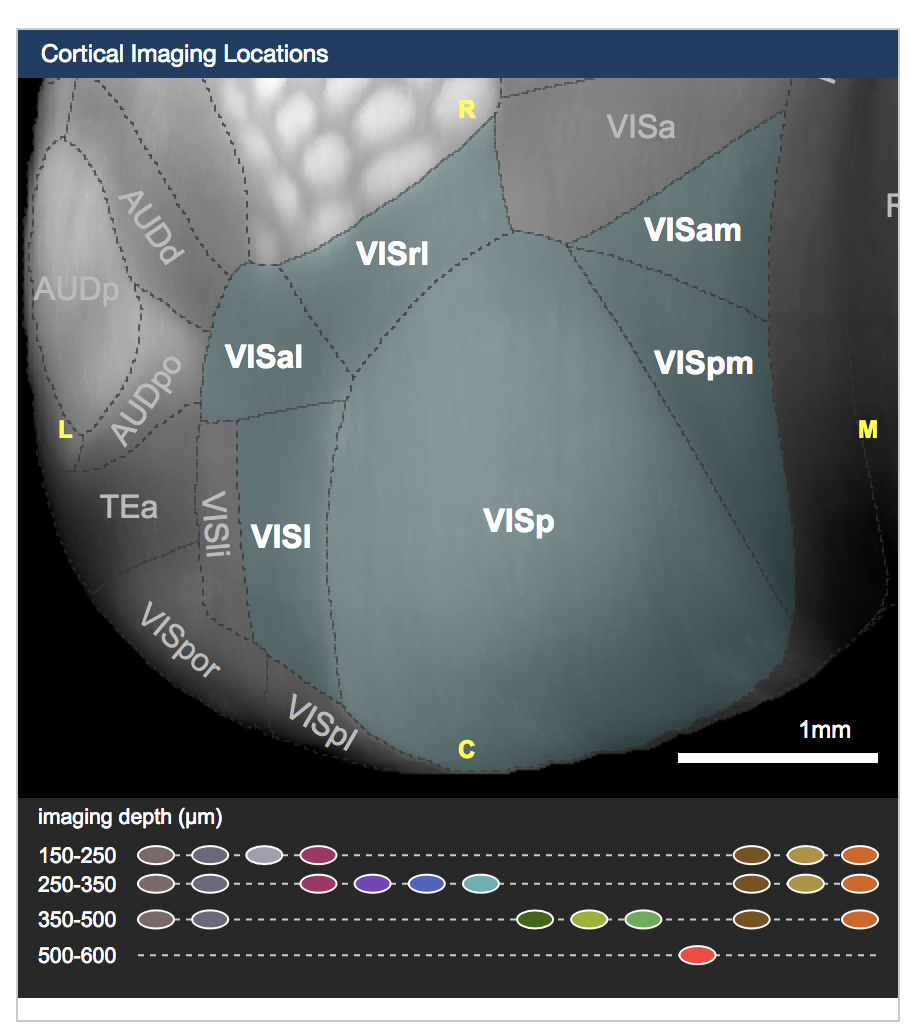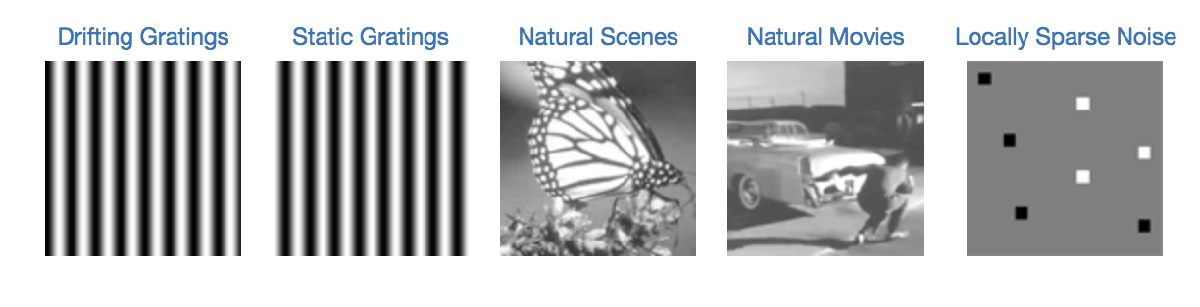

## Getting started

The toolbox classes are contained within the `bot` namespace within matlab. Once the toolbox is added to the `matlab `path, you can access the main classes:

`bot.sessionfilter` — Retrieve and manage lists of available experimental sessions, filtering them by various experimental parameters.

`bot.session` — Encapsulate, manage and access data for a single experimental season.

We'll go through the usage of these classes during the tutorial. Right now we need to initialise the toolbox and download the initial manifest of experiments provided by the Allen Brain Observatory. The BOT only downloads what data is necessary, beginning with the experimental metadata. The neural recordings are quite large, and so raw data for experiments is only downloaded when it is needed for analysis. All data is transparantly cached by the toolbox to save network bandwidth.

**Searching and filtering experimental data**

First let's quickly explore the range of data made available. Listing, filtering and searching through the experimental data is managed by the `bot.sessionfilter` class.

bosf = bot.sessionfilter

bosf =   sessionfilter with properties:

       valid_session_table: [1368×15 table]
    filtered_session_table: [1368×15 table]
                  stimulus: {9×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [23×1 double]
              container_id: [456×1 double]
                session_id: [1368×1 double]
              session_type: {4×1 cell}
                  cre_line: {13×1 cell}
        eye_tracking_avail: [2×1 logical]


We can look at the metadata for some of the experimental sessions contained in the `.valid_session_table` property:

head(bosf.valid_session_table)

ans = 8×15 table
      date_of_acquisition       experiment_container_id    fail_eye_tracking        id        imaging_depth                      name                       specimen_id       stimulus_name                                                   storage_directory                                                targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen            cre_line       
    ________________________    _______________________    _________________    __________    _____________    _________________________________________    ___________    

In order to locate experiments of interest, we need to filter the available sessions down to just the few we want. To accomplish this, `bot.sessionfilter` provides several `filter_...()` methods:

methods(bosf)


Methods for class bot.sessionfilter:

clear_filters                                          get_all_session_types                                  
filter_session_by_cre_line                             get_all_stimuli                                        
filter_session_by_eye_tracking                         get_all_targeted_structures                            
filter_sessions_by_container_id                        get_filtered_sessions                                  
filter_sessions_by_imaging_depth                       get_summary_of_containers_along_depths_and_structures  
filter_sessions_by_session_id                          get_summary_of_containers_along_imaging_depths         
filter_sessions_by_session_type                        get_summary_of_containers_along_targeted_structures    
filter_sessions_by_stimuli                             get_targeted_structure_acronyms                        
filter_sessions_by_targeted_structure                  get_total_num_of_c

- `filter_session_by_cre_line()` — Choose sessions that contain data only from the desired CRE driver line

- `filter_session_by_eye_tracking()` — Choose seesions that contain valid eye tracking data

- `filter_sessions_by_container_id()` — Choose sessions that match a given container ID, if you know it

- `filter_sessions_by_imaging_depth()` — Choose sessions that match a particular imaging depth

- `filter_sessions_by_session_id()` — Choose sessions matching a given session ID, if you know it

- `filter_sessions_by_session_type()` — Choose sessions matching a session type (set of stimuli; see the Brain Observatory website for details)

- `filter_sessions_by_stimuli()` — Choose sessions containing responses to desired stimuli

- `filter_sessions_by_targeted_structure()` — Choose sessions where a desired brain structure was imaged

Let's begin by picking experiments from a single visual area. The method `get_all_targeted_structures` returns a list of the visual areas available in the database:

bosf.get_all_targeted_structures()

ans = 6×1 cell array
    {'VISal'}
    {'VISam'}
    {'VISl' }
    {'VISp' }
    {'VISpm'}
    {'VISrl'}


Primary visual cortex is named `'VISp'` in the Brain Observatory data set. We can now filter the experimental sessions to only those recorded in primary visual cortex:

bosf.filter_sessions_by_targeted_structure('VISp')

ans =   sessionfilter with properties:

       valid_session_table: [1368×15 table]
    filtered_session_table: [432×15 table]
                  stimulus: {9×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [15×1 double]
              container_id: [144×1 double]
                session_id: [432×1 double]
              session_type: {4×1 cell}
                  cre_line: {13×1 cell}
        eye_tracking_avail: [2×1 logical]


 There are now 138 experiments remaining out of the original 543. Let's filter further by selecting experiments that contain drifing grating responses:

bosf.get_all_stimuli

ans = 9×1 cell array
    {'drifting_gratings'        }
    {'locally_sparse_noise_4deg'}
    {'locally_sparse_noise_8deg'}
    {'natural_movie_one'        }
    {'natural_movie_three'      }
    {'natural_movie_two'        }
    {'natural_scenes'           }
    {'spontaneous'              }
    {'static_gratings'          }


bosf.filter_sessions_by_stimuli('drifting_gratings')

ans =   sessionfilter with properties:

       valid_session_table: [1368×15 table]
    filtered_session_table: [144×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [15×1 double]
              container_id: [144×1 double]
                session_id: [144×1 double]
              session_type: {'three_session_A'}
                  cre_line: {13×1 cell}
        eye_tracking_avail: [2×1 logical]


bosf.filter_sessions_by_session_id(704298735)

ans =   sessionfilter with properties:

       valid_session_table: [1368×15 table]
    filtered_session_table: [1×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 175
              container_id: 701412138
                session_id: 704298735
              session_type: {'three_session_A'}
                  cre_line: {'Cux2-CreERT2'}
        eye_tracking_avail: 0


## Get a single experimental session

The method `.get_filtered_sessions()` returns the identified sessions as `bot.session` objects. These are smart wrappers for the experimental data, which at first only hold the metadata for each experimental session. The raw data will only be downloaded when it is needed.

bos = bosf.get_filtered_sessions()

bos =   session with properties:

               sSessionInfo: [1×1 struct]
    strLocalNWBFileLocation: []


bos.get_metadata()

ans = struct with fields:
                        age: '112 days'
                        sex: 'male'
              imaging_depth: '175 microns'
         targeted_structure: 'VISp'
        ophys_experiment_id: 704298735
    experiment_container_id: 701412138
              device_string: 'Nikon A1R-MP multiphoton microscope. CAM2P.2 Please see http://help.brain-map.org/display/observatory/Allen+Brain+Observatory for details'
          excitation_lambda: '910 nanometers'
                  indicator: 'GCaMP6f'
                        fov: '400x400 microns (512 x 512 pixels)'
                   genotype: 'Cux2-CreERT2/wt;Camk2a-tTA/wt;Ai93(TITL-GCaMP6f)/wt'
         session_start_time: 'Thu May 31 14:46:41 2018'
               session_type: 'three_session_A'
              specimen_name: 'Cux2-CreERT2;Camk2a-tTA;Ai93-382421'
               generated_by: {4×1 cell}
                   cre_line: 'Cux2-CreERT2/wt'
           imaging_depth_um: 175
                   age_days: 112
               

The `session` object provides a number of methods to access the experimental data. These methods generally match the Brain Observatory API.

methods(bos)


Methods for class bot.session:

EnsureCached                                get_metadata                                get_session_type                            
get_cell_specimen_ids                       get_motion_correction                       get_spontaneous_activity_stimulus_table     
get_cell_specimen_indices                   get_neuropil_r                              get_stimulus                                
get_corrected_fluorescence_traces           get_neuropil_traces                         get_stimulus_epoch_table                    
get_demixed_traces                          get_pupil_location                          get_stimulus_table                          
get_dff_traces                              get_pupil_size                              get_stimulus_template                       
get_fluorescence_timestamps                 get_roi_ids                                 list_stimuli                                
get_fluorescence_traces             

- `get_max_projection()` — Return an image of the maximum intensity projection of the fluorescence data

- `get_dff_traces()` — Return fluorescence traces from individual cells after demixing,  neuropil correction and dF/F0 conversion

- `get_pupil_location()` — Return the time trace of estimated pupil locations during the experiment

- `get_pupil_size()` — Return the time trace of estimated pupil size during the experiment 

- `get_running_speed()` — Return the time trace of running speed exhibited by the animal during the experiment

## Examine an overview of the imaging data

Let's look at the imaged field, by visualizing the maximum intensity projection of the data. By examining the session metadata we can see that the field of view is 400x400µm (512x512 pixels). We can plot a scale bar appropriately.

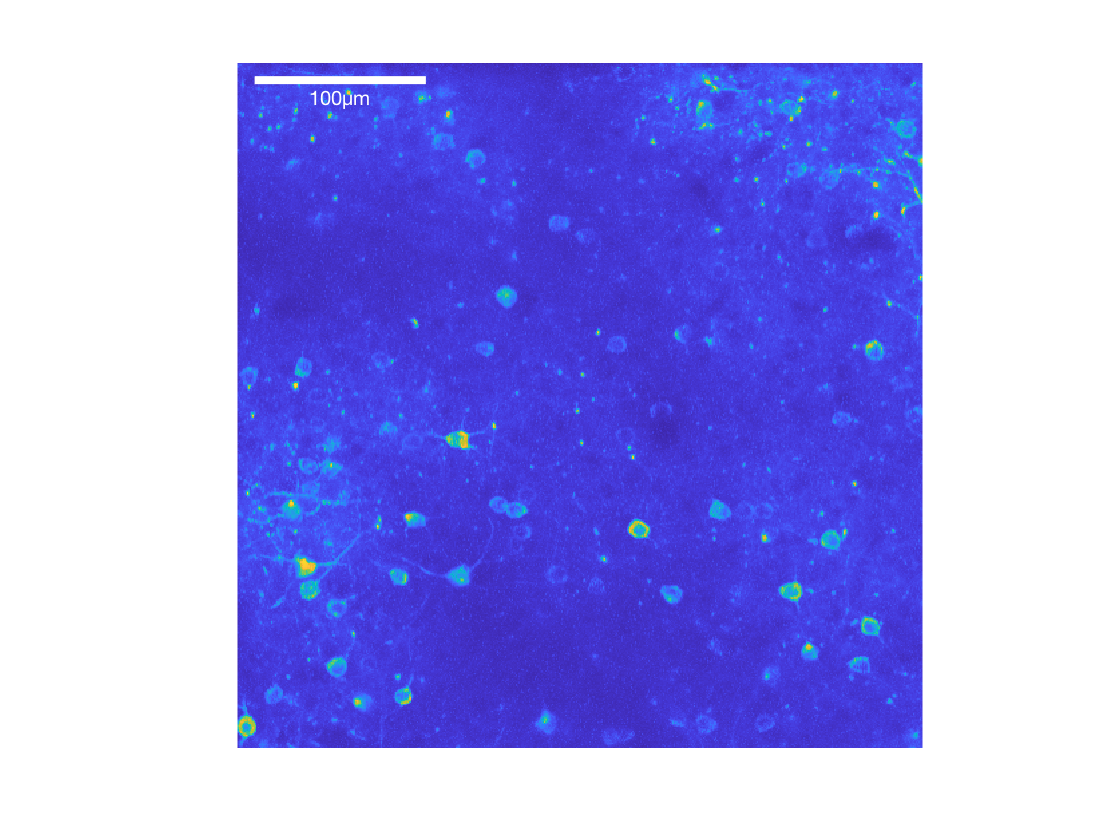

fPixelSize = 400/512;
vfXLoc = linspace(0, 400-fPixelSize, 512) + fPixelSize / 2;
figure;
imagesc(vfXLoc, vfXLoc, bos.get_max_projection());
colormap default;
axis square tight off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

Helpfully, the locations and shapes of ROIs defining each neuron are supplied to us from the Brain Observatory data. We can access these ROIs using the `get_roi_mask() `method. This method returns a structure containing ROIs than can be plotted and manipulated using Matlab built-in commands.

sROIs = bos.get_roi_mask()

sROIs = struct with fields:
    Connectivity: 8
       ImageSize: [512 512]
      NumObjects: 95
    PixelIdxList: {1×95 cell}
          Labels: {1×95 cell}


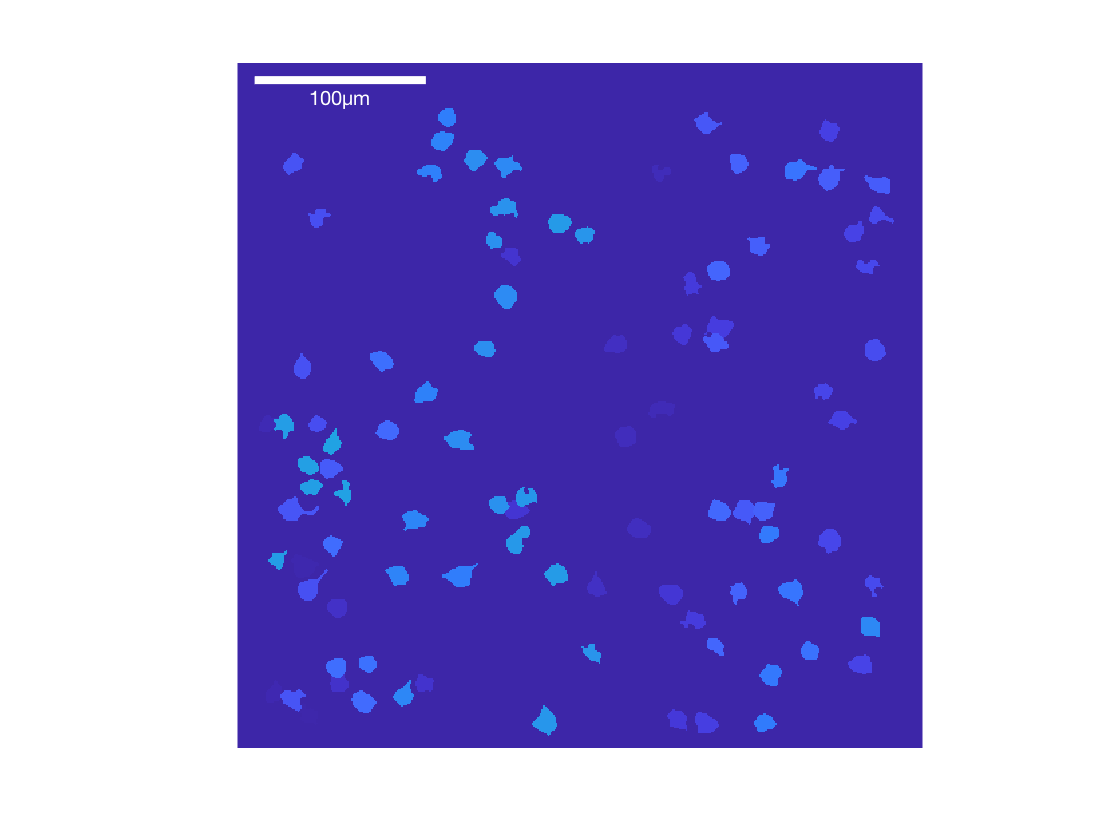

figure;
image(vfXLoc, vfXLoc, labelmatrix(sROIs));
axis tight square off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

## Analysing cell responses

Now let's get access to the fluorescence traces for all ROIs, using the `get_corrected_fluroescence_traces()` method. This method returns a `[Tx1]` vector of timestamps, and a `[TxN]` matrix of fluorescence responses for each cell, at each corresponding timestamp.

[vtTimestamps, mfTraces] = bos.get_dff_traces();
whos vtTimestamps mfTraces

  Name                   Size               Bytes  Class       Attributes

  mfTraces          115498x95            43889240  single                
  vtTimestamps      115498x1               923986  duration              



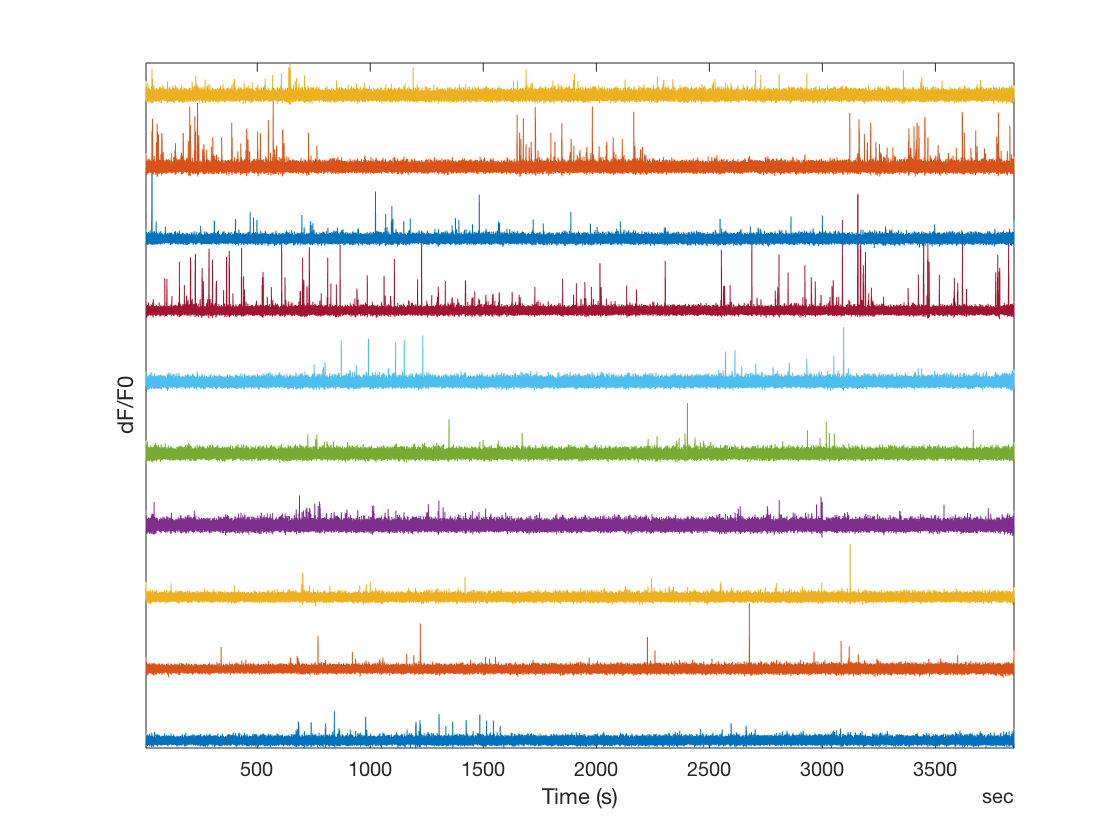

figure;
plot(vtTimestamps, bsxfun(@plus, mfTraces(:, 1:10:end), (0:10:size(mfTraces, 2))/3))
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

Not all cells respond equally, as is clear from the traces above. One approach to select ROIs with robust responses is to measure the skewness of the individual responses over time. Healthy pyramidal cells with good quality data will respond sparsely but robustly over the course of an experiment, with strong fluorescence signals well above the imaging noise floor. These response characteristics lead to a high skewness in the response distribution. We can use the built-in Matlab `skewness()` command to estimate the skewness for each ROI.

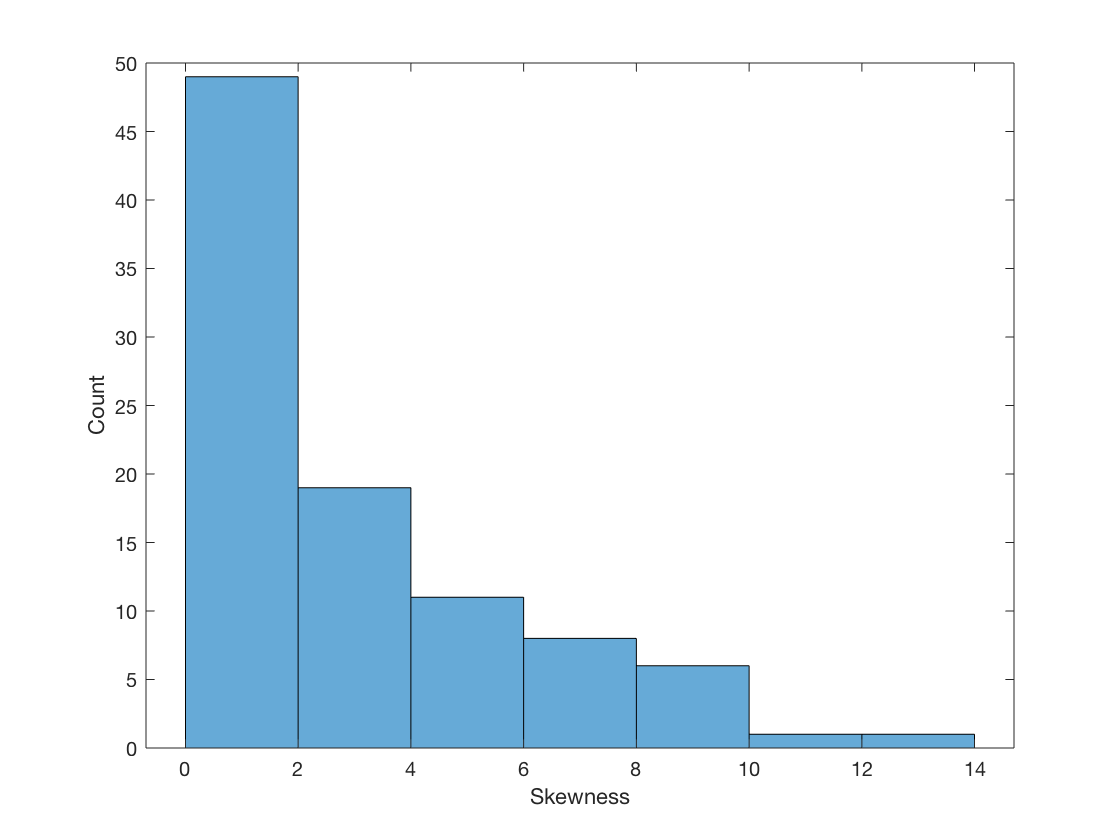

vfSkewness = skewness(mfTraces);
figure;
histogram(vfSkewness);
xlabel('Skewness'); ylabel('Count')

Let's compare the response of a high-skewness ROI with a low-skewness ROI.

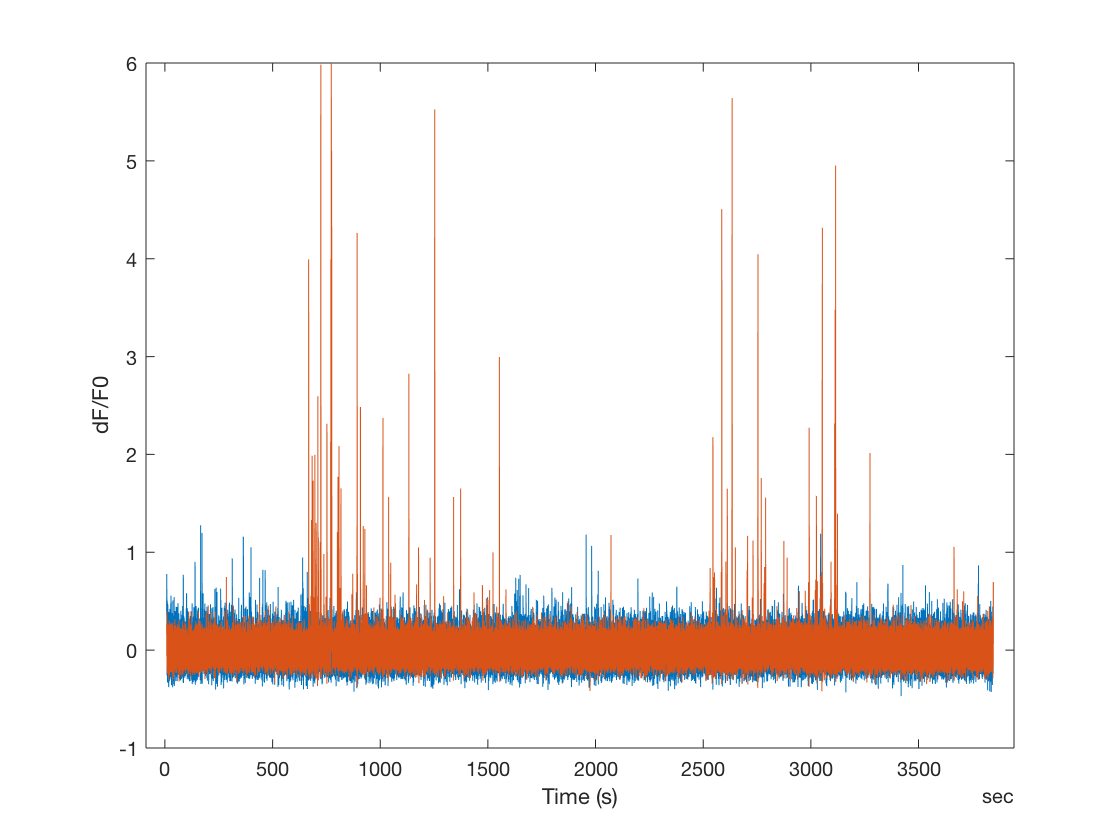

[~, vnSortOrder] = sort(vfSkewness);
plot(vtTimestamps, mfTraces(:, vnSortOrder([5 end])))
xlabel('Time (s)'); ylabel('dF/F0');

Generally a skewness threshold of 1 or 2 is sufficient, which leaves that majority of cells in this experiment.

## Analysing stimulus responses

This animal was presented with an array of stimuli, including drifting sine-wave grating stimuli. Let's find the responses to individual trials of the drifting gratings, separated by drift direction, and build tuning curves for each ROI.

First we need to access the stimulus information, using the `bos.get_stimulus_epoch_table()` method.

bos.get_stimulus_epoch_table()

ans = 7×3 table
           stimulus            start_frame    end_frame
    _______________________    ___________    _________

    {'drifting_gratings'  }         746         18780  
    {'natural_movie_three'}       19713         37777  
    {'natural_movie_one'  }       38681         47712  
    {'drifting_gratings'  }       48616         66649  
    {'spontaneous'        }       66799         75711  
    {'natural_movie_three'}       75712         93775  
    {'drifting_gratings'  }       94678        115240  


This table lists the epochs during which the various stimulus paradigms were presented. `'drifting_gratings'` stimuli were presented in three blocks, from the beginning to the end of the session. To obtain the imaging frames corresponding to the individual visual stimuli, we need the `bos.get_stimulus_table()` method:

tDriftingGratings = bos.get_stimulus_table('drifting_gratings');
head(tDriftingGratings)

ans = 8×5 table
    temporal_frequency    orientation    blank_sweep    start_frame    end_frame
    __________________    ___________    ___________    ___________    _________

             2                270             0             746           806   
            15                180             0             836           896   
             2                135             0             927           986   
             4                 90             0            1017          1077   
             1                315             0            1107          1167   
             2                  0             0            1198          1257   
             4                 90             0            1288          1348   
             8                315             0            1378          1438   


Each visual stimulus is listed in order of presentation, along with the stimulus parameters (temporal frequency, orientation) and the start and stop imaging frames that correspond to the given stimulus presentation. To extract the neural responses to each stimulus, we need to loop over presentations and estimate the response for each cell during each presentation. For example, an algorithm such as in the code below:

nROI = 1;
for nPresentation = 1:size(tDriftingGratings, 1)
    vnFrames = tDriftingGratings{1, 'start_frame'}:tDriftingGratings{1, 'end_frame'};
    vfResponse(nPresentation) = nanmean(mfTraces(vnFrames, nROI));
end

This is presented as pseudo-code, as this approach is inefficient (note the warning about preallocation) and no error-checking is performed. Luckily, the BOT provides a utility function `bot.util.StimulusAlignedResp()`, which takes care of estimating responses to presentations. By default, responses during a presentation are averaged using `nanmean()`. If you prefer another way to estimate a response, you can pass a function handle to `bot.util.StimulusAlignedResp()`.

mfResponses = bot.util.StimulusAlignedResp(tDriftingGratings, mfTraces)

mfResponses = 628×95 single matrix
    0.0503    0.0032    0.0424    0.0160    0.0158    0.0034   -0.0046    0.0122    0.0321    0.0064   -0.0035    0.0488    0.0078   -0.0076    0.0129    0.0189    0.0330    0.0017    0.0788    0.0117    0.0248    0.0138    0.0190    0.0041    0.0070    0.0223    0.0161    0.0045    0.0343    0.0094    0.1171    0.0753    0.0123    0.0035   -0.0010    0.0467    0.0469    0.4967    0.0090    0.0522    0.0369    0.0147   -0.0060   -0.0007    0.0252    0.0194    0.0119    0.0084    0.0089    0.0639
    0.0010    0.0182    0.0371    0.0659    0.0242    0.0384   -0.0234   -0.0133    0.0164   -0.0088   -0.0128    0.0133   -0.0079    0.0200    0.0261    0.0136    0.0212    0.0124    0.0282    0.0097   -0.0085   -0.0112    0.0271    0.0267    0.0287    0.0113   -0.0127    0.0036    0.2106    0.0505    0.0039    0.0295    0.0035    0.0288    0.0076    0.0340    0.0213   -0.0024    0.0023   -0.0111    0.0200   -0.0079   -0.0093    0.0174    0.0214    0.0332   -

`mfResponses` contains one row for each stimulus presentation. We need to re-sort these according to stimulus parameters, and use blank stimuli to help estimate a baseline response. Let's statrt with blank responses.

% Locate "blank" stimulus presentations
vbBlankPresentations = tDriftingGratings{:, 'blank_sweep'} == 1;

% Extract neural responses to blank presentations
vfBlankResponses = nanmean(mfResponses(vbBlankPresentations, :))

vfBlankResponses = 1×95 single row vector
    0.0045   -0.0018    0.0066    0.0023    0.0065    0.0086    0.0068    0.0033    0.0125    0.0075    0.0050    0.0016    0.0039    0.0059    0.0021    0.0663    0.0093    0.0060    0.0069    0.0055    0.0022    0.0007    0.0046    0.0074    0.0085    0.0053    0.0105    0.0102    0.0096   -0.0012    0.0104    0.0073    0.0066    0.0043    0.0050    0.0051    0.0029    0.0022    0.0023    0.0050    0.0050    0.0053    0.0075    0.0034    0.0059    0.0065    0.0048    0.0062    0.0025    0.0002


Now we subtract "blank" responses from evoked visual responses, to remove any spontaneous activity and correct for poor baseline estimation.

mfResponsesCorrected = mfResponses - vfBlankResponses;

Each particular visual stimulus was presented multiple times. We therefore need to collect and sort responses to multiple trials of the same visual stimulus. We will assign a unique stimulus ID to each stimulus, using the built-in function `unique()`.

[tUniqueStimuli, ~, vnPresentationStimID] = unique(tDriftingGratings(:, 1:2), 'rows', 'sorted')

tUniqueStimuli = 70×2 table
    temporal_frequency    orientation
    __________________    ___________

            1                   0    
            1                  45    
            1                  90    
            1                 135    
            1                 180    
            1                 225    
            1                 270    
            1                 315    
            2                   0    
            2                  45    
            2                  90    
            2                 135    
            2                 180    
            2                 225    
            2                 270    
            2                 315    


vnPresentationStimID =     15
    37
    12
    19
     8
     9
    19
    32
     6
    25


Each presentation is now assigned a stimulus ID, listed in `vnPresentationStimID`, which corresponds to the stimulus parameters in rows of `tUniqueStimuli`. We can now collect 